# Thermoeconomic Diagnosis Demo

Use ThermoeconomicDiagnosis function to compare two states of the plant and to make diagnosis

#### Select and read the data model file

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\orcvcr\orcvcr_model.json";
data=ReadDataModel(file);

#### Select the parameters

States=convertCharsToStrings(data.StateNames);
State=convertStringsToChars(States(4));
DiagnosisMethod='WASTE_INTERNAL';

#### Compute Diagnosis Analysis

res=ThermoeconomicDiagnosis(data,'State',State,'DiagnosisMethod',DiagnosisMethod,'Show',true);

Fuel Impact:         43.800 (kW)
Malfunction Cost:   133.732 (kW)


Diagnosis Summary - TCND35

Key        MF(kW)     ΔI(kW)     ΔR(kW)    ΔPt(kW)    MF*(kW)    MR*(kW)   ΔPt*(kW)
————————————————————————————————————————————————————————————————————————————————————
BLR        -6.943      7.400     37.757      0.000     -6.943     87.425      0.000
TRB        -0.780     -0.500      8.786      0.000     -1.328     24.637      0.000
PMP        -0.034      0.130      0.596      0.000     -0.060      1.443      0.000
CMP        -0.855     -0.690     10.521      0.000     -1.496     35.417      0.000
EVAP       -0.023    -10.620      0.000     -9.690     -0.051     -0.053    -89.932
GEN         0.044      0.070      0.111      0.000      0.078      0.330      0.000
VEXP        0.000      0.000      0.000      0.000      0.000      0.000      0.000
CND        -0.070     -0.070      0.000      0.000     -1.870     -3.797      0.000
ENV        -8.660     -4.280     57.770     -9.690    -11.670  

#### Show Graph Results

Show Default graph (Malfuncion Cost Table)

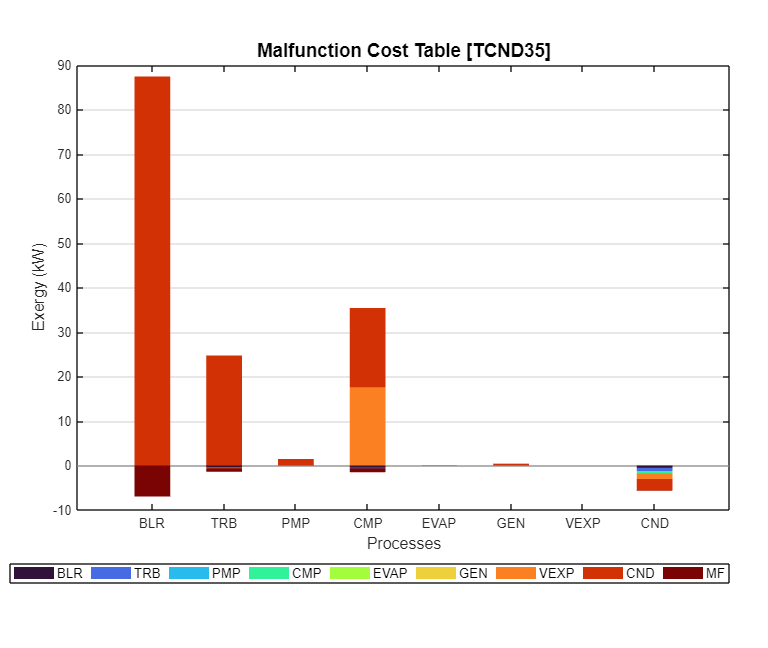

ShowGraph(res,'ShowOutput',false);

Show Total Malfunction Cost Graph

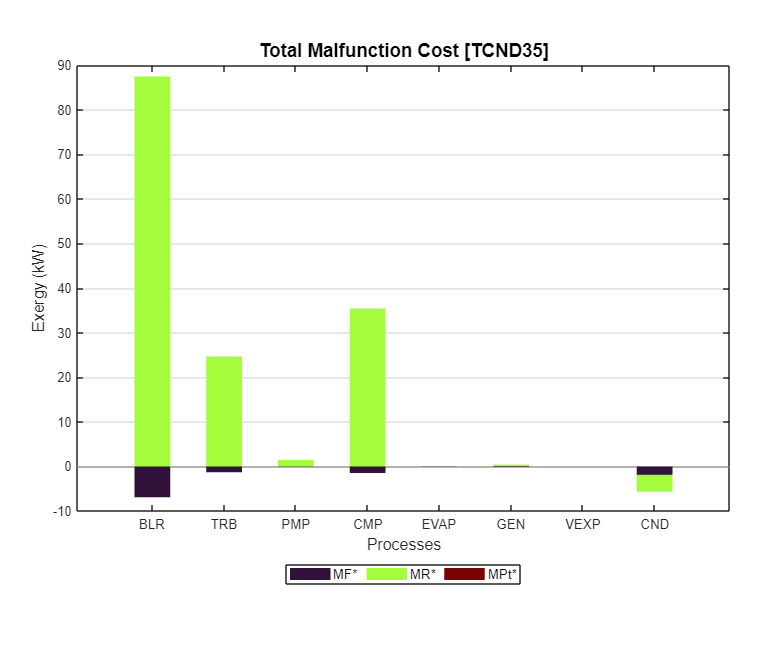

ShowGraph(res,'Graph','tmfc');

Show Fuel Impact graph

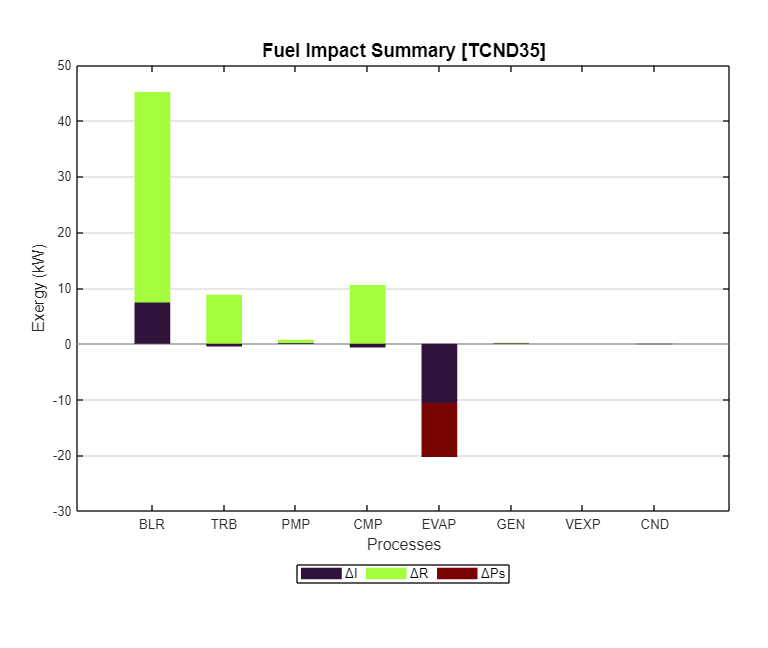

ShowGraph(res,'Graph','dft');

#### Additional Help

help ThermoeconomicDiagnosis

 ThermoeconomicDiagnosis - Compare to states of the plant and make a thermoeconomic diagnosis
    This function makes a thermoeconomic diagnosis of the plant, comparing two plant states. 
    Two different methods could be used to analyze the increase in waste generation: 
    'WASTE_EXTERNAL' accounts for the increase in the cost of waste, and
    'WASTE_INTERNAL' internalises the waste cost to the productive processes that generate them. 
    The data model must have at least two states defined to perform the analysis.
  
  Syntax
 	res = ThermoeconomicDiagnosis(data,Name,Value)
  
  Input Arguments
    data - cReadModel object containing the data information
     
  Name-Value Arguments
    Reference State - Reference State. If not provided first state is used
      char array
    State - State to compare. If not provided second state is used
      char array
    DiagnosisMethod - Select the method to compute diagnosis
      'WASTE_EXTERNAL' Waste a